# Exercise 1: Text Extraction

In this exercise, you will learn how to perform text extraction from images using Optical Character Recognition (OCR). OCR is a powerful technique that allows you to convert different types of documents, such as scanned paper documents, PDFs, or images into editable and searchable data. We will utilize the Tesseract OCR engine to automatically detect and recognize text within an image. This exercise will guide you through selecting an image file, extracting the text content, and saving the results for further analysis. By the end of this exercise, you will have a fundamental understanding of how to implement OCR in MATLAB, enabling you to automate the process of text extraction from images.

### Task1: Read the image file and display the image

Description:

- This section prompts the user to select an image file using a file dialog. The dialog filters the file types to show only image files (`.png`, `.jpg`, `.jpeg`) by default, but allows selection of any file type.

- The full path of the selected image is constructed using `fullfile`, which combines the directory path and the file name.

- The `imread` function reads the image into the MATLAB workspace as a matrix, which contains the pixel data.

- The `imshow` function displays the image in a figure window, allowing you to visually confirm that the correct image has been loaded.

Expected Result:

- The selected image is displayed in a figure window. This step confirms that the image is loaded successfully into the workspace and is ready for text extraction in the subsequent steps.

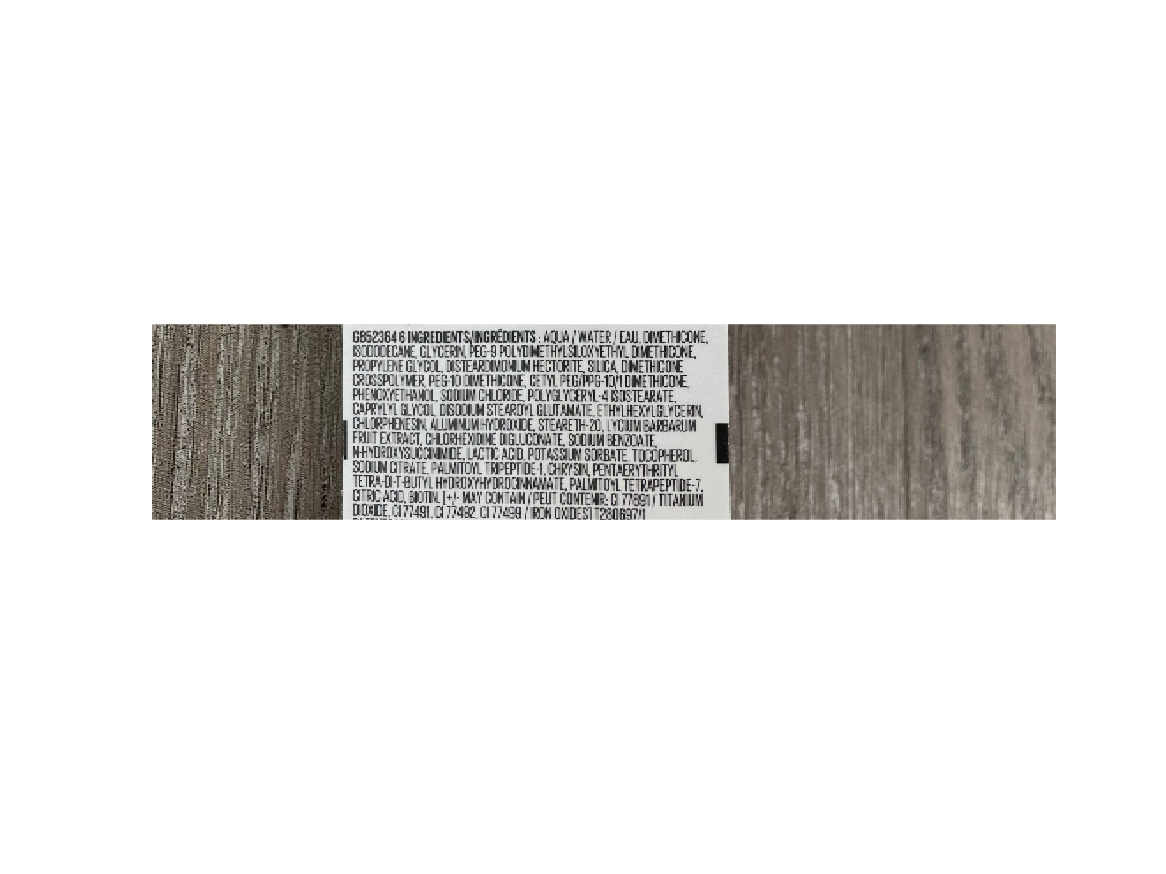

[imageName, imagePath] = uigetfile({'*.png;*.jpg;*.jpeg',...
    'Image Files (*.png, *.jpg, *.jpeg)'; '*.*', 'All Files (*.*)'},...
    'Select an image',...
    fullfile(userpath, 'Repositories', 'beyond-the-label', 'data', 'images'));
imageFullPath = fullfile(imagePath, imageName);
image = imread(imageFullPath);
imshow(image);

### Task 2: Extract the text from the image

Description:

- This section performs OCR on the loaded image using the `ocr` function, which analyzes the image and attempts to recognize any text.

- The recognized text is stored in `ocrResults.Text`. The `strtrim` function is then used to remove any leading or trailing whitespace from the extracted text.

Expected Result:

- `extractedText` contains the text extracted from the image. The quality of the extracted text depends on the clarity and formatting of the text in the image.


ocrResults = ocr(image);
extractedText = strtrim(ocrResults.Text)

extractedText =     '(852364 6 INGREDIENTS/INGREDIENTS : AQUA / WATER / EAU, DIMETHICONE,
     
     ISODODECANE, GLYCERIN, PEG- Es, DUETHCONE
     PROPYLENE GLYCOL, DISTEARDIMONIUM pa Ne ETHICONE
     CROSSPOLYMER, PEG-10 DIMETH Honk: CETYL PEG/PPG
     
     AERVTHRITYL
     TETRA-DIT-BUTYL HYDROXYHYDROG ANAMATE DAMON TETRAPEPTIDE-7,
     Li [+[-MAY Sonn | PEUT UT CONTENR. Ol 17891 | TITANIUM'


### Task 3: Save the extracted text in a MAT file

Description:

- This step saves the extracted text to a MAT-file named `new_product_ingredients.mat`. This file will be used in subsequent exercises (e.g., Exercise 3) to analyze the text further.

Expected Result:

- A MAT-file is created in the current working directory containing the variable `extractedText`. This file serves as a persistent storage of the extracted text data for later use.

save('new_product_ingredients.mat', "extractedText");

### Task 4: Calculate Accuracy of Extrated Text

Description:

- Use `getGroundTruthText` to obtain the actual text for the selected image.

- Calculate the accuracy of the extracted text using the `evaluateOCRAccuracy` helper function.

Expected Results:

- You will obtain an accuracy score expressed as a percentage, which reflects the OCR performance. A higher percentage indicates a closer match between the extracted text and the ground truth, signifying better OCR accuracy.

- The accuracy score will help you assess the effectiveness of the OCR process and identify areas for potential improvement, such as image quality or preprocessing techniques.

% Get the ground truth text for the image
groundTruthText = getGroundTruthText(imageFullPath);

% Evaluate the accuracy of the extracted text
accuracy = evaluateOCRAccuracy(extractedText, groundTruthText);

fprintf('OCR Accuracy: %.2f%%\n', accuracy);

OCR Accuracy: 35.35%
